clear all;
fileName = '5'

fileName = '5'

CaliLeft = 60/288; CaliRight = 60/361; % unit is mm/pixel
LeftImagePath = dir(['E:/BubbleRisingUltimate/4mmGasBubbleRising/4mmGasBubbleRising/',fileName , '/*S0001000*.tif']);
RightImagePath = dir(['E:/BubbleRisingUltimate/4mmGasBubbleRising/4mmGasBubbleRising/',fileName , '/*S0002000*.tif']);
LeftImage = zeros(1024,1024,length(LeftImagePath)); RightImage = LeftImage;
for i = 1:length(LeftImagePath)
    LeftImage(:,:,i) = imread([LeftImagePath(i).folder,'/',LeftImagePath(i).name]);
    RightImage(:,:,i) = imread([RightImagePath(i).folder,'/',RightImagePath(i).name]);
end

LeftImage = double(LeftImage); RightImage = double(RightImage);
LeftMedian = median(LeftImage, 3);
RightMedian = median(RightImage, 3);
for i = 1:length(LeftImagePath)
    LeftImage(:,:,i) = abs(LeftImage(:,:,i) - LeftMedian);
    RightImage(:,:,i) = abs(RightImage(:,:,i) - RightMedian);
end

LeftImageBW = zeros(1024,1024,length(LeftImagePath)); RightImageBW = LeftImage;
for i = 1:length(LeftImagePath)
    LeftImageBW(:,:,i) = imbinarize(LeftImage(:,:,i),2000);
    RightImageBW(:,:,i) = imbinarize(RightImage(:,:,i), 2000);
end

LeftImageBW = logical(LeftImageBW);
RightImageBW = logical(RightImageBW);
regionInfo = regionprops(LeftImageBW(:,:,200),'basic');
figure()
clf;
Area = cat(1, regionInfo.Area);
[M, I] = max(Area)

M = 30

I = 5

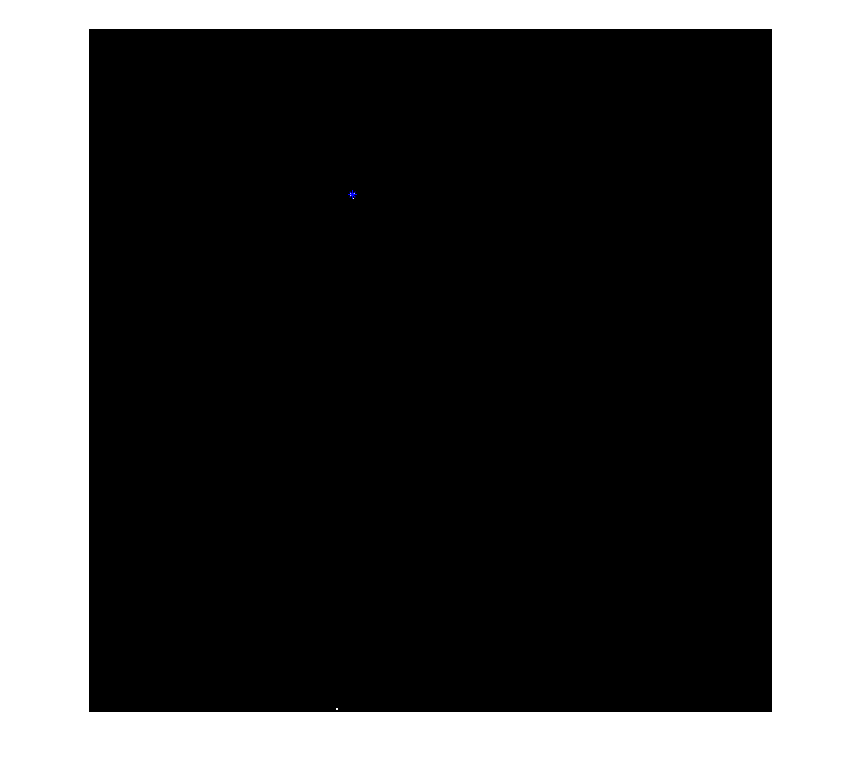

imshow(LeftImageBW(:,:,200));
centroids = cat(1,regionInfo.Centroid);
hold on
plot(centroids(I,1),centroids(I,2),'b*')
hold off

LeftCenter = []; RightCenter = [];
for i = 1:length(LeftImagePath)
    regionInfo = regionprops(LeftImageBW(:,:,i),'basic');
    Area = cat(1, regionInfo.Area);
    [M, I] = max(Area); centroids = cat(1,regionInfo.Centroid);
    LeftCenter = [LeftCenter; centroids(I,:)];
    
    regionInfo = regionprops(RightImageBW(:,:,i),'basic');
    Area = cat(1, regionInfo.Area);
    [M, I] = max(Area); centroids = cat(1,regionInfo.Centroid);
    RightCenter = [RightCenter; centroids(I,:)];
end

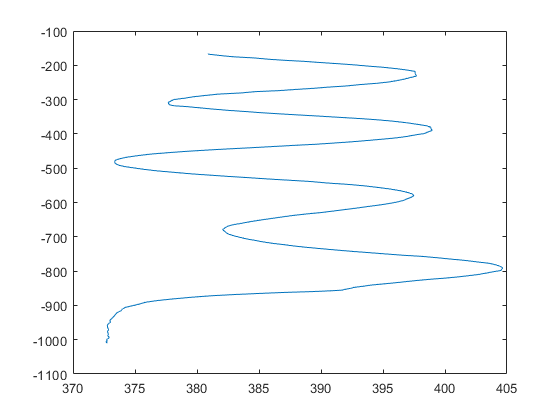

LeftCenter(:,2) = -LeftCenter(:,2);
RightCenter(:,2) = -RightCenter(:,2);
figure()
plot(LeftCenter(:,1),LeftCenter(:,2));

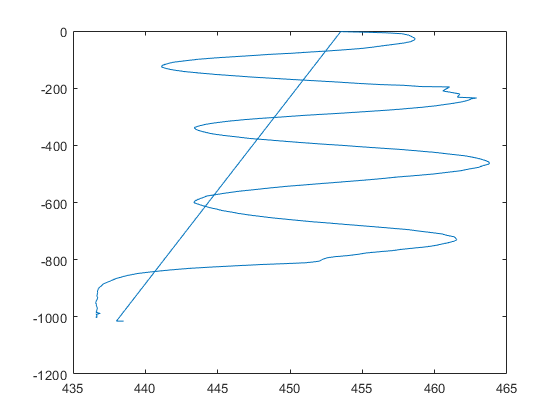

figure()
plot(RightCenter(:,1), RightCenter(:,2));

j = 100;
while j <= length(LeftImagePath)
    distance = abs(RightCenter(j,2) - RightCenter(j - 1, 2));
    if distance > 100
        break
    end
    j = j + 1;
end
j = j - 1;
fprintf(['last frame:',num2str(j)]);

last frame:211

for i = 1:j
    LPoints{i} = LeftCenter(i,:) * CaliLeft;
    RPoints{i} = RightCenter(i,:) * CaliRight;
end

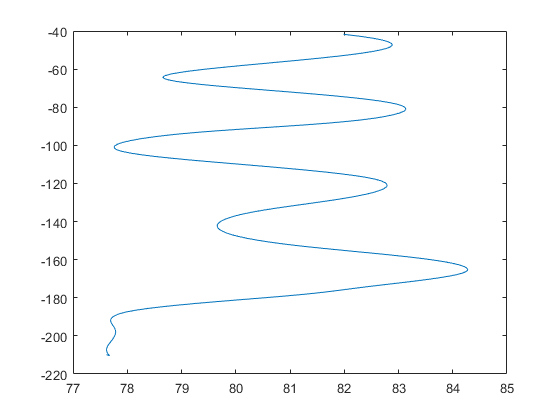

tracksL=simpletracker(LPoints, 'Method', 'NearestNeighbor','MaxLinkingDistance',10, 'MaxGapClosing', 21);
trajL=rt2traj(LPoints,tracksL,5);
trajL=trajp2traj(trajL,1/250);
figure()
plot(trajL.x, trajL.y)

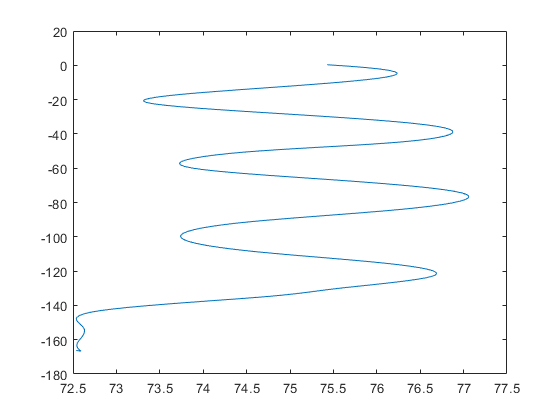

tracksR=simpletracker(RPoints,'Method', 'NearestNeighbor','MaxLinkingDistance',10, 'MaxGapClosing', 21);
trajR=rt2traj(RPoints,tracksL,5);
trajR=trajp2traj(trajR,1/250);
figure()
plot(trajR.x, trajR.y)

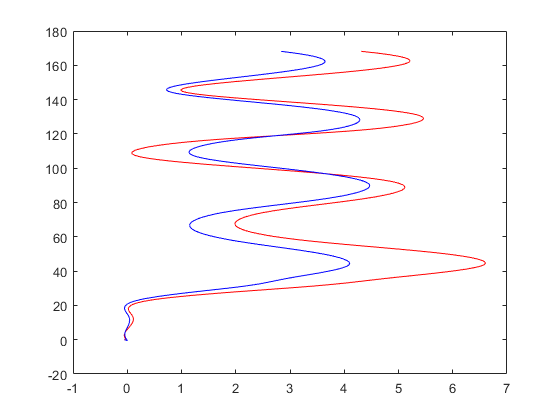

u = trajL.u; v = trajR.u; w = trajL.v;
x = trajL.x; x = x - x(5);
y = trajR.x; y = y - y(5);
z = trajL.y; z = z - z(1);
figure()
plot(x,z,'r-');
hold on;
plot(y,z,'b-');
hold off

traj3D = [x,y,z,u,v,w];


save(['./data/matlabPTVinfo/', fileName, '.mat'],'traj3D');